**Project 11: Inspection Threshold Detection (Intersection + Logic)**

A quality metric Q(x) and a threshold line T (x) determine pass/fail.

Tasks

1. Define Q(x) as a quadratic model on x = 0 : 0.5 : 20.

2. Define a linear threshold T (x).

3. Plot both models and find where Q(x) ≥ T (x).

4. Output the pass/fail intervals in MATLAB (e.g., ranges of x).

5. Summarize results in 4–6 sentences

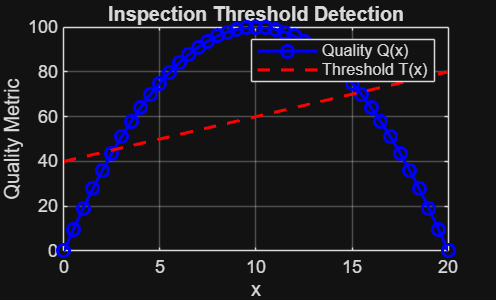

x = 0:0.5:20; %These are the variables
Q = -x.^2 + 20*x; %Defining Q(x) as a quadratic model
T = 2*x + 40; %Defining T(x) as a linear model 

%This part of code line 6-12 allows for a visual graph
figure; 
plot(x, Q, 'b-o', 'LineWidth', 1.5); hold on; %Plotting the Q function
plot(x, T, 'r--', 'LineWidth', 1.5); %Plotting T Function 
grid on; %Allows for grid 
xlabel('x'); ylabel('Quality Metric'); %Labeling the x-axis
legend('Quality Q(x)', 'Threshold T(x)'); %allows for a legend
title('Inspection Threshold Detection'); %Title of graph 


%% 3. Find where Q(x) >= T(x)
pass = Q >= T; %I created pass as a variable and when Q is greater than or equal to T

% Extract the x values that satisfy the condition
pass_x = x(pass);

%% 4. Output Pass/Fail Intervals
if isempty(pass_x) %Similar to a checklist, statement runs through an array of 0 and 1 and keeps the 1's
    fprintf('The item fails at all inspection points.\n'); %prints a message saying "Fails at all inspection points"
else
    min_pass = min(pass_x); %a minimum value 
    max_pass = max(pass_x); %a maximum value 
    fprintf('Pass Interval: x ranges from %.1f to %.1f\n', min_pass, max_pass); %Displays a message 
end

Pass Interval: x ranges from 3.0 to 15.0
